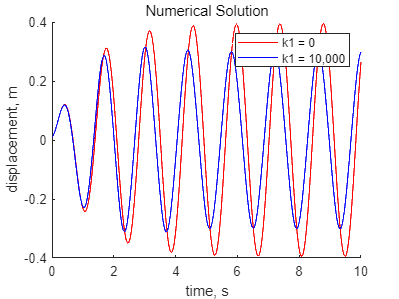

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 비선형 경화 스프링과 선형 스프링일 때의 진폭 비교

clear; clc;
global m k c F w k1
m = 100; k = 2000; x0 = 0.01; v0 = 0.1; c = 170;
t0 = 0; tf = 10;
F = 300; w = sqrt(k/m);

hold on
% k1 = 0일 때의 해
k1 = 0;
[t, x] = ode45('func_2_98', t0:0.0001:tf, [x0;v0]);
plot(t, x(:,1), 'r')
title('Numerical Solution');
xlabel('time, s');
ylabel('displacement, m');

% k1 = 10000일 때의 해
k1 = 10000;
[t, x] = ode45('func_2_98', t0:0.0001:tf, [x0;v0]);
plot(t, x(:,1), 'b')
title('Numerical Solution');
xlabel('time, s');
ylabel('displacement, m');
legend('k1 = 0', 'k1 = 10,000');
hold off